%{
radial clearance
axial clearance
coil h
coil r in
coil r out
wire diameter
coil former radial t
coil former axial t
mag bot axial t
mag top axial t
armature r
chamfer r
chamfer h
shell t
packing ratio
current safety factor
air gap
relative permeability
permeability
copper wire current capacity
%}
clear
syms c_r c_a h_C r_Cout D_w t_cfr t_cfa t_mba t_mta...
    r_A r_cham h_cham t_shell PR CSF h_air mu mu0 CWCC

magnetic_top_r = t_shell + r_Cout + c_r

$$magnetic\_top\_r = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

r_Cin = r_A + c_r + t_cfr

$$r\_Cin = c_{r}+r_{A}+t_{\mathrm{cfr}}$$

R_path1 = r_Cout / (mu * mu0 * t_mta * pi * 0.25 * (magnetic_top_r + r_Cout + c_a))

$$R\_path1 = \frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}$$

latex(R_path1)

ans = '\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu _{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}'

h_coilformer = h_C + 2 * t_cfa

$$h\_coilformer = h_{C}+2\,t_{\mathrm{cfa}}$$

shell_rin = r_Cout + c_r

$$shell\_rin = c_{r}+r_{\mathrm{Cout}}$$

shell_rout = magnetic_top_r

$$shell\_rout = c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}$$

R_path2_a = (t_mta + h_coilformer + t_mba / 2 - c_a) /...
    (mu * mu0 * pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_a = \frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

    
R_path2_b = c_a / (mu0 *pi * (magnetic_top_r^2 - shell_rin^2))

$$R\_path2\_b = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path2 = R_path2_a + R_path2_b

$$R\_path2 = \frac{c_{a}}{\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\left({\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\right)}$$

R_path3_a = 0.5 * t_shell /...
    (mu * mu0 * t_mba * pi * (shell_rin + t_shell * 0.5))

$$R\_path3\_a = \frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}$$

R_path3_b = c_r / (mu0 * t_mba * pi * (shell_rin - 0.5 * c_r))

$$R\_path3\_b = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}$$

R_path3_c = (r_Cout - (r_A + c_r)) /...
        (mu * mu0 * t_mba * pi * 0.5 * ((r_A + c_r) + r_Cout))

$$R\_path3\_c = -\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

R_path3_d = c_r / (mu0 * t_mba * pi * (r_A + 0.5 * c_r))

$$R\_path3\_d = \frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}$$

R_path3_e = r_A / (mu * mu0 * t_mba * pi * 0.5 * r_A)

$$R\_path3\_e = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }$$


R_path3 = R_path3_a + R_path3_b + R_path3_c + R_path3_d + R_path3_e

$$R\_path3 = \frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}$$

theta = atan(h_cham / (r_A - r_cham))

$$theta = \mathrm{atan}\left(\frac{h_{\mathrm{cham}}}{r_{A}-r_{\mathrm{cham}}}\right)$$

R_path4_a = (0.5 * (h_coilformer + t_mba) + c_a - h_air) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_a = \frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4_b_1 = h_air / (mu0 * pi * r_cham^2)

$$R\_path4\_b\_1 = \frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }$$

R_path4_b_2 = (h_air * cos(theta)) / (mu0 * pi * (r_A^2 - r_cham^2)/cos(theta))

$$R\_path4\_b\_2 = \frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}$$

R_path4_b = 1 / (1/R_path4_b_1 + 1/R_path4_b_2)

$$R\_path4\_b = \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}$$

R_path4_c = (0.5 * (h_coilformer + t_mta) + c_a) /...
    (mu * mu0 * pi * r_A^2)

$$R\_path4\_c = \frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_path4 = R_path4_a + R_path4_b + R_path4_c

$$R\_path4 = \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi }$$

R_total = R_path1 + R_path2 + R_path3 + R_path4

$$R\_total = \begin{array}{l} \frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

A_w = D_w^2 * pi * 0.25

$$A\_w = \frac{\pi \,{D_{w}}^{2}}{4}$$

N = floor(h_C/D_w) * floor((r_Cout - r_Cin)/D_w) * PR

$$N = \mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor$$

I = CWCC * A_w * CSF

$$I = \frac{\pi \,\mathrm{CSF}\,\mathrm{CWCC}\,{D_{w}}^{2}}{4}$$

NI = N * I

$$NI = \frac{\pi \,\mathrm{CSF}\,\mathrm{CWCC}\,{D_{w}}^{2}\,\mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }{4}$$

var2 = double(subs(NI,[D_w,PR,h_C,r_Cin,r_Cout,CSF,CWCC],...
    [0.26E-3,0.8,25E-3,6.5E-3,12E-3,0.75,10E6]))

var2 = 642.2119

phi = NI / R_total

$$phi = \begin{array}{l} \frac{\pi \,\mathrm{CSF}\,\mathrm{CWCC}\,{D_{w}}^{2}\,\mathrm{PR}\,\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor \,\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }{4\,\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\left({r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\right)\,\left(\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\right)}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{1}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{2}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{2}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{2}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag_1 = 0.5 * (phi * R_path4_b_2/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * r_cham^2)

$$Fmag\_1 = \begin{array}{l} \frac{{\mathrm{CSF}}^{2}\,{\mathrm{CWCC}}^{2}\,{D_{w}}^{4}\,{\mathrm{PR}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor }^{2}\,{\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }^{2}}{32\,{\mu_{0}}^{3}\,{r_{\mathrm{cham}}}^{2}\,\pi \,{\sigma_{2}}^{2}\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }+\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{2}\,\sigma_{1}}\right)}^{2}\,{\sigma_{1}}^{2}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\sigma_{2}\,\sigma_{1}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\\ \sigma_{2}={r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\\ \sigma_{3}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag_2 = 0.5 * cos(theta) * (phi * R_path4_b_1/(R_path4_b_1 + R_path4_b_2))^2 /...
    (mu0 * pi * (r_A^2 - r_cham^2)/cos(theta))

$$Fmag\_2 = \begin{array}{l} \frac{{\mathrm{CSF}}^{2}\,{\mathrm{CWCC}}^{2}\,{D_{w}}^{4}\,{\mathrm{PR}}^{2}\,{h_{\mathrm{air}}}^{2}\,{\left\lfloor \frac{h_{C}}{D_{w}}\right\rfloor }^{2}\,{\left\lfloor -\frac{c_{r}+r_{A}-r_{\mathrm{Cout}}+t_{\mathrm{cfr}}}{D_{w}}\right\rfloor }^{2}}{32\,{\mu_{0}}^{3}\,{r_{\mathrm{cham}}}^{4}\,\pi \,\sigma_{2}\,{\left(\frac{h_{\mathrm{air}}}{\mu_{0}\,{r_{\mathrm{cham}}}^{2}\,\pi }+\frac{h_{\mathrm{air}}}{\mu_{0}\,\pi \,\sigma_{2}\,\sigma_{1}}\right)}^{2}\,\sigma_{1}\,{\left(\frac{1}{\frac{\pi \,\mu_{0}\,{r_{\mathrm{cham}}}^{2}}{h_{\mathrm{air}}}+\frac{\pi \,\mu_{0}\,\sigma_{2}\,\sigma_{1}}{h_{\mathrm{air}}}}+\frac{2}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi }+\frac{c_{a}}{\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{A}\right)}+\frac{c_{r}}{\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(\frac{c_{r}}{2}+r_{\mathrm{Cout}}\right)}+\frac{h_{C}-c_{a}+2\,t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}+t_{\mathrm{mta}}}{\mu \,\mu_{0}\,\pi \,\sigma_{3}}+\frac{c_{a}+\frac{h_{C}}{2}-h_{\mathrm{air}}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mba}}}{2}}{\sigma_{4}}+\frac{c_{a}+\frac{h_{C}}{2}+t_{\mathrm{cfa}}+\frac{t_{\mathrm{mta}}}{2}}{\sigma_{4}}+\frac{t_{\mathrm{shell}}}{2\,\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{\mathrm{Cout}}+\frac{t_{\mathrm{shell}}}{2}\right)}-\frac{2\,\left(c_{r}+r_{A}-r_{\mathrm{Cout}}\right)}{\mu \,\mu_{0}\,t_{\mathrm{mba}}\,\pi \,\left(c_{r}+r_{A}+r_{\mathrm{Cout}}\right)}+\frac{4\,r_{\mathrm{Cout}}}{\mu \,\mu_{0}\,t_{\mathrm{mta}}\,\pi \,\left(c_{a}+c_{r}+2\,r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{{h_{\mathrm{cham}}}^{2}}{{\left(r_{A}-r_{\mathrm{cham}}\right)}^{2}}+1\\ \sigma_{2}={r_{A}}^{2}-{r_{\mathrm{cham}}}^{2}\\ \sigma_{3}={\left(c_{r}+r_{\mathrm{Cout}}+t_{\mathrm{shell}}\right)}^{2}-{\left(c_{r}+r_{\mathrm{Cout}}\right)}^{2}\\ \sigma_{4}=\mu \,\mu_{0}\,{r_{A}}^{2}\,\pi \end{array}$$

Fmag = Fmag_1 + Fmag_2

func_Fmag = matlabFunction(Fmag)

func_Fmag = function_handle with value:
    @(CSF,CWCC,D_w,PR,c_a,c_r,h_C,h_air,h_cham,mu,mu0,r_A,r_Cout,r_cham,t_cfa,t_cfr,t_mba,t_mta,t_shell)(CSF.^2.*CWCC.^2.*D_w.^4.*PR.^2.*h_air.^2.*1.0./mu0.^3.*1.0./r_cham.^2.*floor(h_C./D_w).^2.*floor(-(c_r+r_A-r_Cout+t_cfr)./D_w).^2.*1.0./(r_A.^2-r_cham.^2).^2.*1.0./((h_air.*1.0./r_cham.^2)./(mu0.*pi)+h_air./(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))).^2.*1.0./(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0).^2.*1.0./(1.0./((mu0.*r_cham.^2.*pi)./h_air+(mu0.*pi.*(r_A.^2-r_cham.^2).*(h_cham.^2.*1.0./(r_A-r_cham).^2+1.0))./h_air)+2.0./(mu.*mu0.*t_mba.*pi)+c_a./(mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_A))+c_r./(mu0.*t_mba.*pi.*(c_r./2.0+r_Cout))+(-c_a+h_C+t_cfa.*2.0+t_mba./2.0+t_mta)./(mu.*mu0.*pi.*((c_r+r_Cout+t_shell).^2-(c_r+r_Cout).^2))+(1.0./r_A.^2.*(c_a+h_C./2.0-h_air+t_cfa+t_mba./2.0))./(mu.*mu0.*pi)+(1.0./r_A.^2.*(c_a+h_C./2.0+t_cfa+t_mta./2.0))./(mu.*mu0.*pi)+t_shell./(mu.*mu0.*t

%var5 = gradient(Fmag)

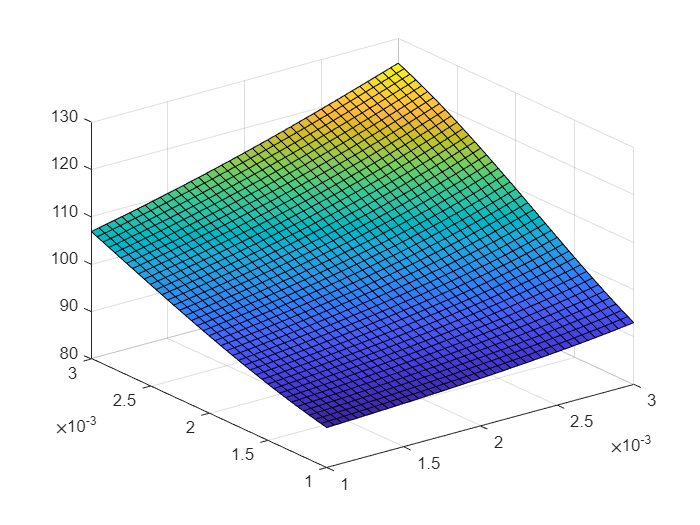


[var_r_cham,var_h_cham] = meshgrid((1:0.05:3)*1E-3,(1:0.05:3)*1E-3);

r = func_Fmag(...
    ...[CSF,CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,    mu, mu0,             r_A, r_Cout,r_cham,    t_cfa,t_cfr, t_mba,t_mta,t_shell]
        0.9,10E6,0.26E-3,0.9,0.05E-3,0.05E-3,50E-3,1E-3, var_h_cham,850,1.25663706212E-6,5E-3,12E-3, var_r_cham,4E-3, 1.5E-3,4E-3, 4E-3, 2E-3   );
surf(var_r_cham,var_h_cham,r)

p1 = double(subs(R_path1,...
    [c_a,    c_r,    mu, mu0,             r_Cout,t_mta,t_shell],...
    [0.05E-3,0.05E-3,850,1.25663706212E-6,12E-3, 4E-3, 2.4E-3 ]))

p1 = 1.3494e+05

p2 =double(subs(R_path2,...
    [c_a,    c_r,    h_C,  mu, mu0,             r_Cout,t_cfa,t_mba,t_mta,t_shell],...
    [0.05E-3,0.05E-3,50E-3,850,1.25663706212E-6,12E-3, 4E-3, 4E-3 ,4E-3 ,2.4E-3 ]))

p2 = 4.9878e+05

p3 = double(subs(R_path3,...
    [c_r,    mu, mu0,             r_A,   r_Cout,t_mba,t_shell],...
    [0.05E-3,850,1.25663706212E-6,4.9E-3,12E-3, 4E-3 ,2.4E-3 ]))

p3 = 1.1239e+06

p4 = double(subs(R_path4,...
    [c_a,    h_C,  h_air,h_cham,mu, mu0,             r_A,   r_cham,t_cfa,t_mba,t_mta],...
    [0.05E-3,50E-3,1E-3, 3E-3,  850,1.25663706212E-6,4.9E-3,4E-3,  4E-3, 4E-3, 4E-3 ]))

p4 = 2.9998e+06

p4_1 = double(subs(R_path4_b_1,...
    [h_air,mu0,             r_cham],...
    [1E-3, 1.25663706212E-6,4E-3  ]))

p4_1 = 1.5831e+07

p4_2 = double(subs(R_path4_b_2,...
    [h_air,h_cham,mu0,             r_A,   r_cham],...
    [1E-3, 3E-3,  1.25663706212E-6,4.9E-3,4E-3  ]))

p4_2 = 2.6111e+06

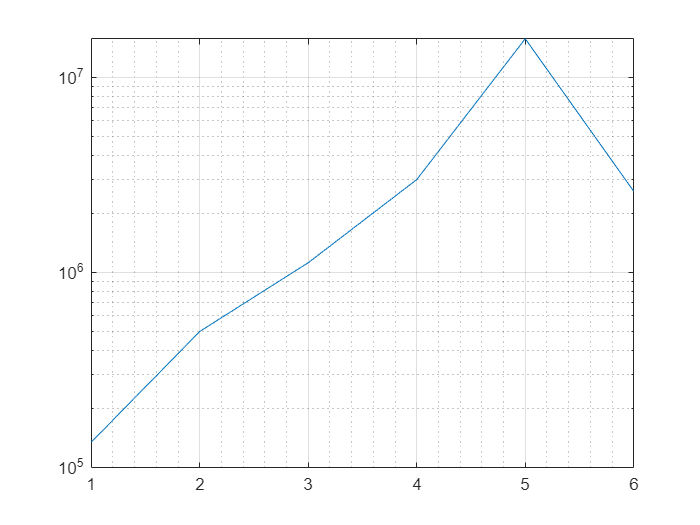

semilogy([p1,p2,p3,p4,p4_1,p4_2]),grid minor,grid on

double(subs(phi,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))

ans = 5.2277e-05

double(subs(Fmag_1,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cout,r_cham,t_cfa,t_cfr, t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,12E-3, 1E-3,  4E-3, 1.5E-3, 4E-3, 4E-3, 2E-3   ]))

ans = 0.4929

double(subs(Fmag_2,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,6.5E-3,12E-3, 1E-3,  1E-3, 4E-3, 4E-3, 2E-3   ]))

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute
values for variables.

Error in sym/double (line 868)
        Xstr = mupadmex('symobj::double', S.s, 0);

Related documentation

double(subs(Fmag,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 1E-3,  850,1.25663706212E-6,5E-3,6.5E-3,12E-3, 1E-3,  1E-3, 4E-3, 4E-3, 2E-3   ]))
double(subs(Fmag,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 2E-3,  850,1.25663706212E-6,5E-3,6.5E-3,12E-3, 1E-3,  1E-3, 4E-3, 4E-3, 2E-3   ]))
double(subs(Fmag,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A, r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.75,10E6,0.26E-3,0.8,0.05E-3,0.05E-3,25E-3,1E-3, 3E-3,  850,1.25663706212E-6,5E-3,6.5E-3,12E-3, 1E-3,  1E-3, 4E-3, 4E-3, 2E-3   ]))



double(subs(NI,...
    [D_w,    PR, h_C,  r_Cin, r_Cout,CSF, CWCC],...
    [0.26E-3,0.9,50E-3,6.6E-3,15E-3, 0.85,10E6]))

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute
values for variables.

Error in sym/double (line 868)
        Xstr = mupadmex('symobj::double', S.s, 0);

Related documentation

double(subs(phi,...
    [CSF, CWCC,D_w,    PR, c_a,   c_r,   h_C,  h_air,h_cham,mu, mu0,             r_A,   r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.85,10E6,0.26E-3,0.9,0.1E-3,0.1E-3,50E-3,1E-3, 0E-3,  850,1.25663706212E-6,4.9E-3,6.6E-3,15E-3, 3E-3,  4E-3, 5E-3, 5E-3, 2.4E-3 ]))
double(subs(Fmag,...
    [CSF, CWCC,D_w,    PR, c_a,    c_r,    h_C,  h_air,h_cham,mu, mu0,             r_A,   r_Cin, r_Cout,r_cham,t_cfa,t_mba,t_mta,t_shell],...
    [0.85,10E6,0.26E-3,0.9,0.05E-3,0.05E-3,50E-3,1E-3, 3E-3,  850,1.25663706212E-6,4.9E-3,6.6E-3,15E-3, 3E-3,  4E-3, 5E-3, 5E-3, 2.4E-3 ]))

%{
radial clearance
axial clearance
coil h
coil r in
coil r out
wire diameter
coil former radial t
coil former axial t
mag bot axial t
mag top axial t
armature r
chamfer r
chamfer h
shell t
packing ratio
current safety factor
air gap
relative permeability
permeability
copper wire current capacity
%}
dFmag_dc_r = diff(Fmag,c_r)

syms d1 d2 d4 d5 l1 l3 l4 mu mu0 CC PR lc dW
%syms NI(d2,l4,CC,PC)
d3 = d4 + 3E-3;
Acoil = 0.5 * l4 * (d2 - d3)
var3 = double(subs(Acoil,[d2,d4,l4],[26E-3,8E-3,25E-3]))
A_w = dW^2 * pi * 0.25
N = floor(l4/dW) * floor(0.5*(d2 - d3)/dW) * PR
I = 10E6 * A_w
NI = N * I
var = double(subs(NI,[PR,d2,d4,dW,l4],[0.75,30E-3,10E-3,0.26E-3,50E-3]))



$$R_{vertial\_in} = \frac{l_a-l_c}{\mu  \cdot S_2} + \frac{l_c}{\mu_0  \cdot S_2}$$


l2 = l4 + 6E-3
la = 0.5 * (l1 + l3) + l2
lb = 0.5 * (0.5 * (d1 + d2) - d5)
S1 = 0.25 * (d1^2 - d2^2)
S2 = 0.25 * pi * (d4^2 - d5^2)
S3 = 0.5 * pi * l1 * lb
S4 = 0.5 * pi * l3 * lb

Rvert_in = (la - lc) / (mu*S2) + lc/(mu0*S2)


$$R_{vertial\_out} = \frac{l_a}{\mu  \cdot S_1}$$


Rvert_out = la / (mu*S1)


$$R_{horizontal\_top} = R_{horizontal\_bottom} = \frac{l_b}{\mu  \cdot S_3}$$


Rhor_top = lb / (mu*S3)
Rhor_bot = lb / (mu*S4)
Rtotal = Rvert_in + Rvert_out + Rhor_top + Rhor_bot
phi = NI / Rtotal
var4 = double(subs(phi,[dW,PR,d1,d2,d4,d5,l1,l3,l4,lc,mu,mu0],[0.26E-3,0.7,30E-3,26E-3,8E-3,0E-3,3E-3,3E-3,25E-3,0.5E-3,850*1.25663706212E-6,1.25663706212E-6]))
Fmag = 0.5 * phi^2 / (mu0 * S2)
double(subs(Fmag,[dW,PR,d1,d2,d4,d5,l1,l3,l4,lc,mu,mu0],[0.26E-3,0.7,30E-3,26E-3,8E-3,0E-3,3E-3,3E-3,25E-3,0.5E-3,850*1.25663706212E-6,1.25663706212E-6]))
double(subs(Fmag,[dW,PR,d1,d2,d4,d5,l1,l3,l4,lc,mu,mu0],[0.26E-3,0.7,30E-3,26E-3,8E-3,4E-3,3E-3,3E-3,25E-3,0.5E-3,850*1.25663706212E-6,1.25663706212E-6]))

phi_res = double(subs(phi,[dW,PR,d1,d2,d4,d5,l1,l3,l4,lc,mu,mu0],[0.26E-3,0.7,30E-3,26E-3,8E-3,0E-3,3E-3,3E-3,25E-3,0.5E-3,850*1.25663706212E-6,1.25663706212E-6]))
S2_res = double(subs(S2,[d4,d5],[8E-3,0E-3]))
0.5*phi_res^2/(S2_res * 1.25663706212E-6)

dMu

dFmag_dmu = diff(Fmag,mu)

dLc

dFmag_dlc = diff(Fmag,lc)

dd1

dFmag_dd1 = diff(Fmag,d1)

dd2

dFmag_dd2 = diff(Fmag,2)

dd4

dFmag_dd4 = diff(Fmag,d4)

dd5

dFmag_dd5 = diff(Fmag,d5)

dl1

dFmag_dl1 = diff(Fmag,l1)

dl3

dFmag_dl3 = diff(Fmag,l3)

dl4

dFmag_dl4 = diff(Fmag,l4)

dCC

dFmag_dCC = diff(Fmag,CC)

dPR

dFmag_dPR = diff(Fmag,PR)

density6061 = 2700;
density430F = 7800;
densityCopper = 8960;
W_copper = PR * 0.25 * l4 * (d2^2 - d3^2) * densityCopper
double(subs(W_copper,[PR,d2,d4,l4],[0.7,27E-3,8E-3,25E-3]))
W_coilformer = 0.25 * (d2^2 * (l2 - l4) + d3^2 * l4 - d4^2 * l2) * density6061
W_shell = 0.25 * (d1^2 - d2^2) * l2 * density430F
W_magtop = 0.25 * ((d1^2 - d5^2) * l1 + (d4^2 - d5^2) * l2 * 0.5) * density430F
W_magbot = 0.25 * (d1^2 - d5^2) * l3 * density430F
W_magpintle = 0.25 * (d4^2 - d5^2) * l2 * 0.5 * density430F
Weight = W_copper + W_coilformer + W_shell + W_magtop + W_magbot + W_magpintle
double(subs(Weight,[PR,d1,d2,d4,d5,l1,l3,l4],[0.8,30E-3,27E-3,8E-3,0E-3,3E-3,3E-3,25E-3]))

dPR

dWeight_dcop = diff(Weight,PR)

dd1

dWeight_dd1 = diff(Weight,d1)

dd2

dWeight_dd2 = diff(Weight,d2)

dd4

dWeight_dd4 = diff(Weight,d4)

dd5

dWeight_dd1 = diff(Weight,d5)

dl1

dWeight_dl1 = diff(Weight,l1)

dl3

dWeight_dl3 = diff(Weight,l3)

dl4

dWeight_dl4 = diff(Weight,l4)